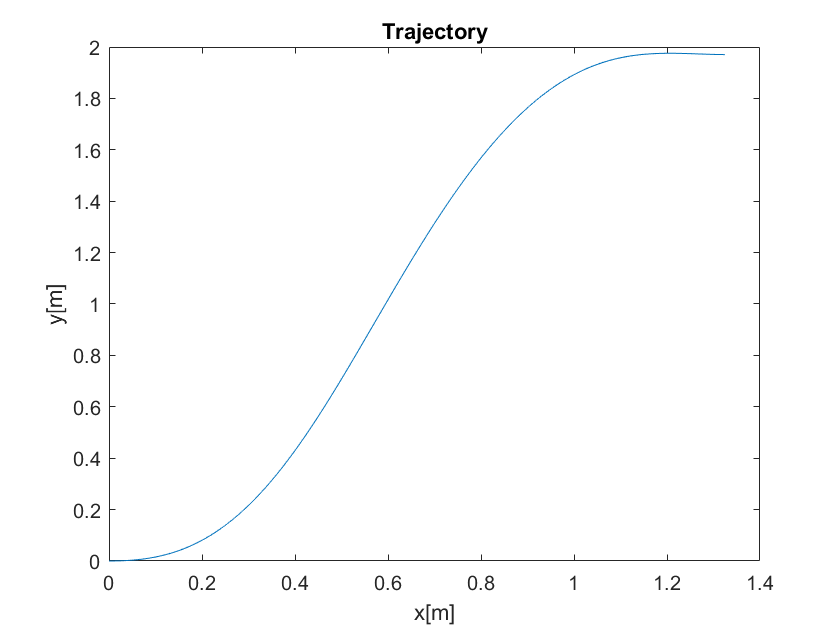

% Code for Rear Wheel Driven Front wheel steered Bicycle Model with some
% given steering input.
% OUTPUT: Trajectory, Yaw Rate , Longitudnal Velocity
% INPUT : R(Driving Force) , Gamma(Steering Angle), Gamma_Dot 

clear all;
close all;

l = 2.5;
d = 1.25;
J = 2500;
m = 1500;
m_0 = (J+m*d^2)/l^2;
omega_gamma = 1.5*pi; %frequency of rotating steering wheel
F_wind = 0;
R = 0;  %%INPUT

tstart = 0;
tend = 2*pi/omega_gamma; % One cycle of steering exitation 
tspan = tstart:0.01:tend;
y0 = [0 0 0 20];
[t,y] = ode45(@(t,y)odefunc(t,y,d,l,m,m_0,F_wind,omega_gamma,R),...
        tspan,y0);

figure(1);
plot(y(:,1),y(:,2)); %Trajectory
xlabel("x[m]");
ylabel("y[m]");
title("Trajectory")

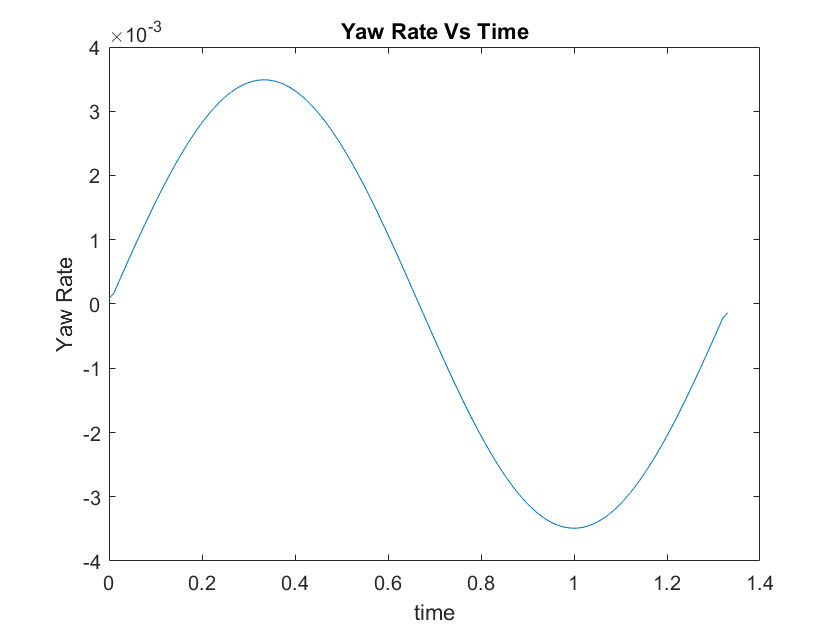


figure(2);
gradient(y(:,3));
plot(t,gradient(y(:,3))); %Yaw Rate
xlabel("time");
ylabel("Yaw Rate");
title("Yaw Rate Vs Time")

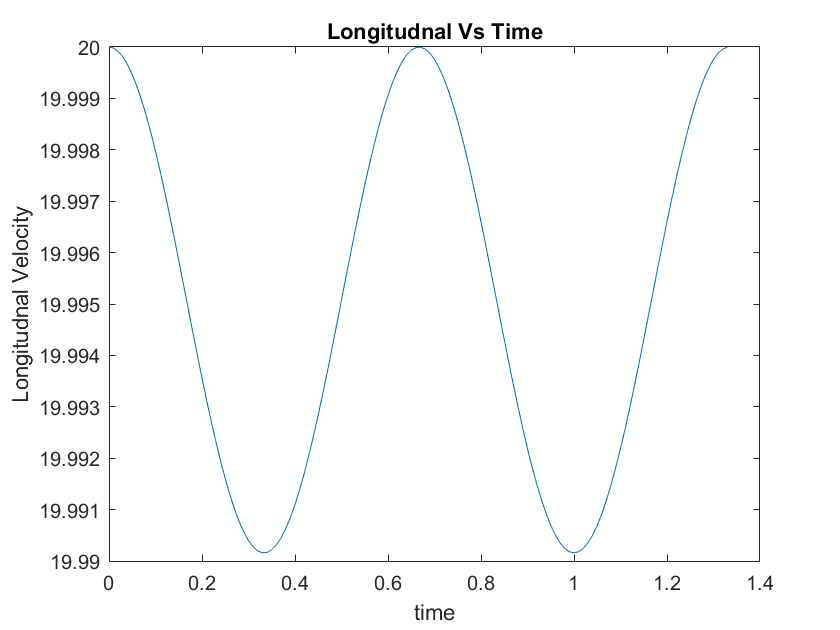


figure(3);
plot(t,y(:,4)); % Longitudnal Velocity
xlabel("time");
ylabel("Longitudnal Velocity");
title("Longitudnal Vs Time")

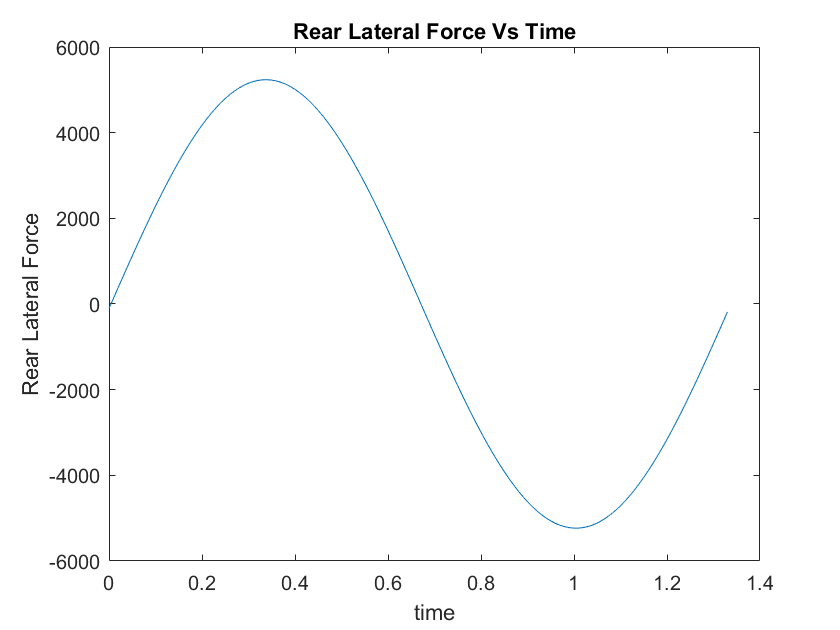


[Frl,Ffl] = LateralForces(t,y,d,l,m,m_0,F_wind,omega_gamma,R);

figure(4);
plot(t,Frl); % Rear Lateral Force
xlabel("time");
ylabel("Rear Lateral Force");
title("Rear Lateral Force Vs Time")

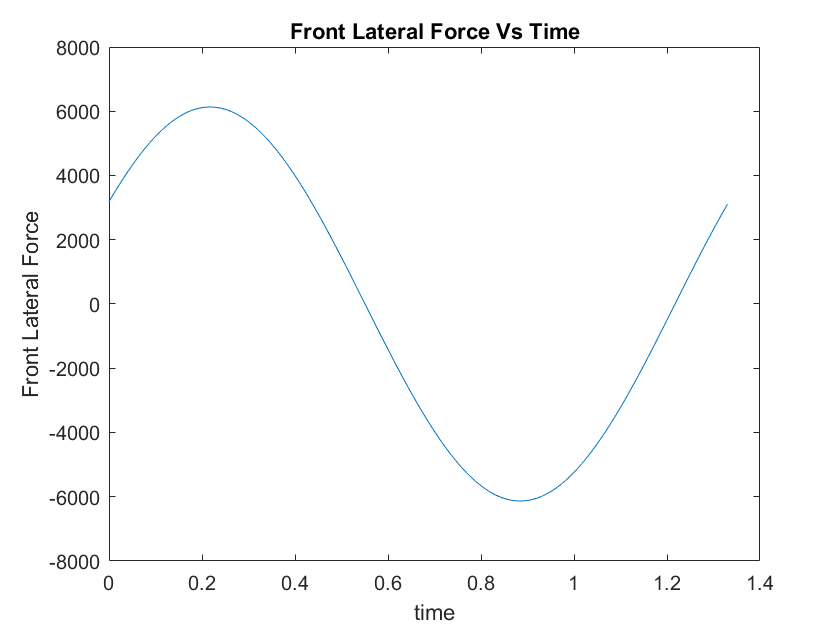


figure(5);
plot(t,Ffl); % Front Lateral Force
xlabel("time");
ylabel("Front Lateral Force");
title("Front Lateral Force Vs Time")


%% ODE Solver to solve for [x,y,psi(yaw angle),sigma(Longitudnal Velocity)]



function dydt = odefunc(t,y,d,l,m,m_0,F_wind,omega_gamma,R)

gamma = (pi/72)*sin(omega_gamma*t); % Given Steering Input %%INPUT
gamma_dot = (omega_gamma*pi/72)*cos(omega_gamma*t); % Derivative of the...
                                                    % Given Steering Input
                                                    % INPUT

dydt(1) = (cos(y(3))-(d/l)*sin(y(3))*tan(gamma)*y(4));
dydt(2) = (sin(y(3))+(d/l)*cos(y(3))*tan(gamma))*y(4);
dydt(3) = tan(gamma)*y(4)/l;
dydt(4) = (R - F_wind - m_0*tan(gamma)*gamma_dot*y(4)/cos(gamma)^2)/...
          (m+m_0*tan(gamma)^2);
      
dydt = dydt';

end

%Calculating Lateral Forces for Front and Rear.
%Equations obtained from Legrangian of second kind. (#Refer project ME542)
%% Function to Calculate Lateral Forces

function [F_rl,F_fl] = LateralForces(t,y,d,l,m,m_0,F_wind,omega_gamma,R)

gamma = (pi/72)*sin(omega_gamma*t); % Given Steering Input %%INPUT
gamma_dot = (omega_gamma*pi/72)*cos(omega_gamma*t); % Derivative of the...
                                                    % Given Steering Input
                                                    % INPUT

F_rl = m.*tan(gamma).*(1-d/l).*y(:,4).^2./l -...
       (m_0 - m.*d./l).*((R-F_wind).*tan(gamma)+m.*gamma_dot.*y(:,4)./cos(gamma).^2)/...
       m+m_0.*tan(gamma).^2;
   
F_fl = (1./cos(gamma)).*(m*d*y(:,4).^2.*tan(gamma)./l.^2 +...
       m_0.*((R-F_wind).*tan(gamma)+m.*gamma_dot.*y(:,4)./cos(gamma).^2)./...
       (m+m_0.*tan(gamma).^2));

end

%Comment #Refer project ME542
